%size(trLb(:,1))
%%%%%%%%%%%%input para%%%%%%%%%%%%%%%%%%%
[rnd_trD, rnd_trLb, rnd_valD, rnd_valLb, rnd_trRegs, rnd_valRegs] = HW2_Utils.getPosAndRandomNeg();
%n = size(rnd_trLb(:,1));
%n=n(:,1);
%k = 2;
%d = size(rnd_trD(:,1));
%d = d(:,1);
%max_epoch = 40;
datasetLbl = rnd_trLb;
datasetD = rnd_trD;
%keySet = [-1 1];
%valSet = [1 2];
%w = zeros(d,k);
%mapper = containers.Map(keySet, valSet);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%tuning para%%%%%%%%%%%%%%%%%%%
eta0 = 1;
eta1 = 100;
C = 10;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%sgd
quadProg


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

wQuad;
biasQuad;

HW2_Utils.genRsltFile(wQuad, biasQuad, 'val' ,'op');


Ub detection 92/92 (100.00%), elapse time:   100.1s
results have been saved to op


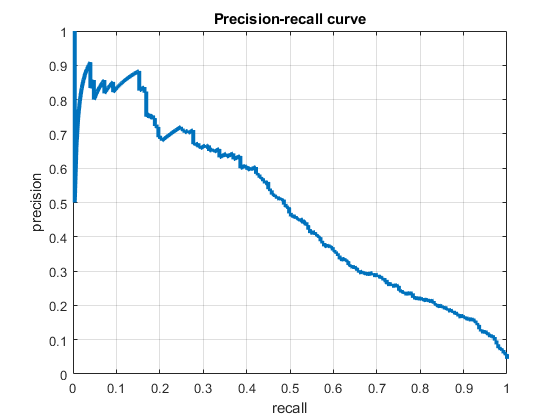

[AP, prec, recall]= HW2_Utils.cmpAP('op', 'val');

AP

AP = 0.4926

prec

prec =     1.0000
    0.5000
    0.6667
    0.7500
    0.8000
    0.8333
    0.8571
    0.8750
    0.8889
    0.9000


recall

recall =     0.0040
    0.0040
    0.0080
    0.0120
    0.0161
    0.0201
    0.0241
    0.0281
    0.0321
    0.0361
